clear; clc; 
path(path,'Subcodes'); 
path(path,'LikelihoodCodes'); 
path(path,'Sims Solver');
run Useful_Transformations

% SET UP THE MODEL
T = 1000; % Number of time points
numStates = 2; % Number of state variables
numObs = 2; % Number of observed variables
numErrors = 3; % Number of error variables
phi = 0.5

phi = 0.5000

psi = -0.1

psi = -0.1000

sigma_r2 = 0.7;
sigma_eps2 = 0.3;
sigma_omega2 = 0.5;
cov_reps = 0;
cov_romega = 0;
cov_epsomega = 0.1;
sigma = [sigma_r2 cov_reps cov_romega;cov_reps sigma_eps2 cov_epsomega;cov_romega cov_epsomega sigma_omega2]

sigma =     0.7000         0         0
         0    0.3000    0.1000
         0    0.1000    0.5000


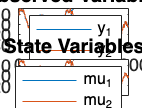


% Initialize variables
mu = zeros(numStates, T); % State variables over time
y = zeros(numObs, T); % Observation variables over time

% Iterating to get all the data
rng('default')
for t=2:T
    err = mvnrnd(zeros(1,3),sigma);
    rt = err(1);
    epst = err(2);
    omegat = err(3);

    mut = [1 0;1 0]*mu(:,t-1)+[rt;0];
    yt = [psi 0;0 phi]*y(:,t-1)+[1 -psi;1-phi 0]*mut+[epst;omegat];

    mu(:,t) = mut;
    y(:,t) = yt;
end

% Plotting
figure;
subplot(2,1,1);
plot(1:T, y');
title('Observed Variables');
legend('y_1', 'y_2');
xlabel('Time t');
ylabel('Observation Values');

subplot(2,1,2);
plot(1:T, mu');
title('State Variables');
legend('mu_1', 'mu_2');
xlabel('Time t');
ylabel('State Values');

% Basic KF estimation
InitialParams = [InvMaxZero(-0.99,-0.1),InvMaxZero(0.99,0.5),0.7,0.3,0.5,0,0,0];
LossToMinmize = @(vparam) -base_kf(vparam,y)/(size(y,2)-1);
% [fhat,EstimParams] = csminwel(LossToMinmize,InitialParams,eye(size(InitialParams,1))*.5,[] ,1e-14,500);

-----------------
-----------------
f at the beginning of new iteration,       123.8948532635
x =      -2.1860513     0.020202707             0.7             0.3
            0.5               0               0               0

Predicted improvement:    56101.282151925
lambda =          1; f =           10.6449079
lambda =    0.33333; f =            8.5163057
lambda =    0.11111; f =            6.5500873
lambda =   0.037037; f =            5.1795386
lambda =   0.012346; f =            6.2636227
lambda =  0.0041152; f =           17.1677313
lambda =  0.0013717; f =           47.9343814
Norm of dx     236.86


ih = 1

----
Improvement on iteration 1 =      118.715314624
-----------------
-----------------
f at the beginning of new iteration,         5.1795386397
x =      -2.8818533      0.22330606      0.71870824       1.3486433
      8.8750456    0.0067714273     0.023472797      -2.2779622

Predicted improvement:        0.062438508
lambda =          1; f =            5.1200511
Norm of dx    0.70535


ih = 1

----
Improvement on iteration 2 =        0.059487533
-----------------
-----------------
f at the beginning of new iteration,         5.1200511070
x =      -3.1371437    -0.028359383      0.46630626       1.1004297
      8.6564472     -0.24567502     -0.22891299      -2.5396579

Predicted improvement:        0.006084219
lambda =          1; f =            5.1198617
lambda =    0.33333; f =            5.1174518
Norm of dx     0.2072


ih = 1

----
Improvement on iteration 3 =        0.002599324
-----------------
-----------------
f at the beginning of new iteration,         5.1174517831
x =      -3.1139844   -0.0045245743      0.49000382       1.1249078
      8.6864443     -0.22198575     -0.20521243      -2.5176923



dx =     0.0067
    0.0101
    0.0117
    0.0116
    0.0369
    0.0094
    0.0095
    0.0019


Correct for low angle: -0.0549421
Predicted improvement:        0.000053107
lambda =          1; f =            5.1176584
lambda =    0.33333; f =            5.1174517
lambda =    0.11111; f =            5.1174439
Norm of dx   0.044311


ih = 1

----
Improvement on iteration 4 =        0.000007862
-----------------
-----------------
f at the beginning of new iteration,         5.1174439208
x =      -3.1132414     -0.00339999      0.49130603       1.1261937
      8.6905468      -0.2209411     -0.20415864      -2.5174864



dx =     0.0005
    0.0017
    0.0024
    0.0020
    0.0104
    0.0014
    0.0014
   -0.0011


Correct for low angle: -0.249264
Predicted improvement:        0.000013798
lambda =          1; f =            5.1174288
Norm of dx   0.011246


ih = 1

----
Improvement on iteration 5 =        0.000015089
-----------------
-----------------
f at the beginning of new iteration,         5.1174288317
x =      -3.1127672   -0.0017474982      0.49368124       1.1281709
      8.7009765     -0.21953782     -0.20272266      -2.5185587



dx =    -0.0006
    0.0009
    0.0020
    0.0012
    0.0118
    0.0006
    0.0007
   -0.0025


Correct for low angle: -0.226558
Predicted improvement:        0.000014927
lambda =          1; f =            5.1174072
lambda =     1.9332; f =            5.1174017
Norm of dx   0.012392


ih = 1

----
Improvement on iteration 6 =        0.000027130
-----------------
-----------------
f at the beginning of new iteration,         5.1174017013
x =      -3.1138637   7.4717347e-05      0.49746849       1.1304984
      8.7238667     -0.21834787     -0.20143858      -2.5233128



dx =    -0.0021
   -0.0000
    0.0014
    0.0001
    0.0144
   -0.0005
   -0.0004
   -0.0046


Correct for low angle: -0.180352
Predicted improvement:        0.000017947
lambda =          1; f =            5.1173705
lambda =     1.9332; f =            5.1173497
lambda =     3.7372; f =            5.1173321
Norm of dx   0.015342


ih = 1

----
Improvement on iteration 7 =        0.000069554
-----------------
-----------------
f at the beginning of new iteration,         5.1173321476
x =      -3.1216955  -5.2794561e-05      0.50268398       1.1309047
       8.777726     -0.22020628     -0.20300208      -2.5403956



dx =    -0.0076
   -0.0026
    0.0008
   -0.0027
    0.0317
   -0.0038
   -0.0035
   -0.0134


Correct for low angle: -0.0718508
Predicted improvement:        0.000040280
lambda =          1; f =            5.1172635
lambda =     1.9332; f =            5.1172206
lambda =     3.7372; f =            5.1171949
Norm of dx   0.035802


ih = 1

----
Improvement on iteration 8 =        0.000137239
-----------------
-----------------
f at the beginning of new iteration,         5.1171949089
x =      -3.1500788   -0.0097630318       0.5058006       1.1209011
      8.8960809      -0.2342455     -0.21622803      -2.5905235



dx =    -0.0020
   -0.0028
   -0.0034
   -0.0033
   -0.0084
   -0.0026
   -0.0026
   -0.0010


Correct for low angle: -0.236295
Predicted improvement:        0.000012517
lambda =          1; f =            5.1171950
lambda =    0.33333; f =            5.1171893
Norm of dx   0.010963


ih = 1

----
Improvement on iteration 9 =        0.000005569
-----------------
-----------------
f at the beginning of new iteration,         5.1171893401
x =      -3.1507527    -0.010685521      0.50465213       1.1198153
      8.8932689     -0.23511837     -0.21710434      -2.5908623



dx =     0.0005
    0.0009
    0.0012
    0.0010
    0.0036
    0.0008
    0.0008
    0.0000


Correct for low angle: -0.651129
Predicted improvement:        0.000006118
lambda =          1; f =            5.1171799
lambda =     1.9332; f =            5.1171760
Norm of dx  0.0041613


ih = 1

----
Improvement on iteration 10 =        0.000013293
-----------------
-----------------
f at the beginning of new iteration,         5.1171760469
x =      -3.1498082   -0.0090385685      0.50692373        1.121688
      8.9001814     -0.23359494     -0.21557478      -2.5908345



dx =     0.0009
    0.0014
    0.0019
    0.0015
    0.0060
    0.0014
    0.0014
    0.0001


Correct for low angle: -0.381673
Predicted improvement:        0.000008285
lambda =          1; f =            5.1171669
Norm of dx   0.006941


ih = 1

----
Improvement on iteration 11 =        0.000009164
-----------------
-----------------
f at the beginning of new iteration,         5.1171668826
x =      -3.1489579   -0.0076020876      0.50886631       1.1232114
      8.9061497     -0.23223754     -0.21422211      -2.5907721



dx =     0.0009
    0.0014
    0.0018
    0.0014
    0.0058
    0.0014
    0.0014
    0.0001


Correct for low angle: -0.394244
Predicted improvement:        0.000007978
lambda =          1; f =            5.1171574
Norm of dx  0.0067077


ih = 1

----
Improvement on iteration 12 =        0.000009499
-----------------
-----------------
f at the beginning of new iteration,         5.1171573839
x =       -3.148083   -0.0061817914      0.51070871       1.1245631
      8.9119162     -0.23086693     -0.21286458      -2.5906507



dx =     0.0011
    0.0017
    0.0020
    0.0014
    0.0065
    0.0016
    0.0016
    0.0002


Correct for low angle: -0.34557
Predicted improvement:        0.000008787
lambda =          1; f =            5.1171474
Norm of dx  0.0076111


ih = 1

----
Improvement on iteration 13 =        0.000009976
-----------------
-----------------
f at the beginning of new iteration,         5.1171474078
x =      -3.1470205   -0.0045232571      0.51273289       1.1259303
      8.9184581     -0.22923736     -0.21125711      -2.5904317



dx =     0.0011
    0.0017
    0.0019
    0.0011
    0.0065
    0.0017
    0.0017
    0.0003


Correct for low angle: -0.347341
Predicted improvement:        0.000008649
lambda =          1; f =            5.1171366
Norm of dx  0.0075571


ih = 1

----
Improvement on iteration 14 =        0.000010809
-----------------
-----------------
f at the beginning of new iteration,         5.1171365993
x =      -3.1458972   -0.0028255405      0.51463574       1.1270634
      8.9249645     -0.22754525     -0.20959092      -2.5901343



dx =     0.0016
    0.0022
    0.0022
    0.0011
    0.0078
    0.0022
    0.0022
    0.0006


Correct for low angle: -0.28285
Predicted improvement:        0.000010212
lambda =          1; f =            5.1171246
Norm of dx   0.009207


ih = 1

----
Improvement on iteration 15 =        0.000012025
-----------------
-----------------
f at the beginning of new iteration,         5.1171245740
x =      -3.1443399  -0.00061768848      0.51683296       1.1281967
       8.932786     -0.22531159      -0.2073925      -2.5895357



dx =     0.0017
    0.0024
    0.0020
    0.0008
    0.0079
    0.0024
    0.0024
    0.0008


Correct for low angle: -0.277077
Predicted improvement:        0.000010280
lambda =          1; f =            5.1171109
Norm of dx  0.0093764


ih = 1

----
Improvement on iteration 16 =        0.000013692
-----------------
-----------------
f at the beginning of new iteration,         5.1171108819
x =      -3.1426239     0.001734604      0.51886415       1.1289924
      8.9407069     -0.22291401     -0.20502738      -2.5887627



dx =     0.0027
    0.0035
    0.0025
    0.0007
    0.0108
    0.0036
    0.0035
    0.0014


Correct for low angle: -0.196599
Predicted improvement:        0.000013883
lambda =          1; f =            5.1170935
Norm of dx   0.013038


ih = 1

----
Improvement on iteration 17 =        0.000017359
-----------------
-----------------
f at the beginning of new iteration,         5.1170935230
x =      -3.1399515    0.0052229278      0.52141193        1.129649
      8.9514919     -0.21933459     -0.20148602      -2.5873152



dx =     0.0032
    0.0040
    0.0024
    0.0001
    0.0114
    0.0041
    0.0041
    0.0020


Correct for low angle: -0.180049
Predicted improvement:        0.000014872
lambda =          1; f =            5.1170726
lambda =     1.9332; f =            5.1170688
Norm of dx   0.014167


ih = 1

----
Improvement on iteration 18 =        0.000024713
-----------------
-----------------
f at the beginning of new iteration,         5.1170688101
x =      -3.1337466     0.013006718      0.52603896       1.1299288
      8.9735695     -0.21132942     -0.19352791      -2.5834826



dx =     0.0026
    0.0030
    0.0010
   -0.0008
    0.0071
    0.0031
    0.0031
    0.0019


Correct for low angle: -0.266005
Predicted improvement:        0.000009986
lambda =          1; f =            5.1170501
lambda =     1.9332; f =            5.1170350
lambda =     3.7372; f =            5.1170122
lambda =     7.2247; f =            5.1169922
Norm of dx   0.009505


ih = 1

----
Improvement on iteration 19 =        0.000076568
-----------------
-----------------
f at the beginning of new iteration,         5.1169922422
x =      -3.1151726     0.034825958      0.53290488       1.1244535
      9.0247874     -0.18902927     -0.17104504      -2.5696493



dx =     0.0146
    0.0161
    0.0016
   -0.0070
    0.0301
    0.0164
    0.0167
    0.0124


Correct for low angle: -0.0471837
Predicted improvement:        0.000045562
lambda =          1; f =            5.1169105
lambda =     1.9332; f =            5.1168517
lambda =     3.7372; f =            5.1167891
Norm of dx   0.046181


ih = 1

----
Improvement on iteration 20 =        0.000203163
-----------------
-----------------
f at the beginning of new iteration,         5.1167890796
x =      -3.0606119     0.095004484      0.53894942       1.0981253
      9.1373386      -0.1278632     -0.10867428      -2.5231836



dx =     0.0294
    0.0294
   -0.0030
   -0.0165
    0.0331
    0.0298
    0.0307
    0.0291


Correct for low angle: -0.0248358
Predicted improvement:        0.000073342
lambda =          1; f =            5.1167036
Norm of dx    0.07607


ih = 1

----
Improvement on iteration 21 =        0.000085440
-----------------
-----------------
f at the beginning of new iteration,         5.1167036392
x =      -3.0312431       0.1244324      0.53592897       1.0816511
      9.1704136    -0.098047115    -0.077932005      -2.4940366



dx =    -0.0007
   -0.0024
   -0.0017
    0.0012
   -0.0172
   -0.0025
   -0.0024
    0.0018


Correct for low angle: -0.133073
Predicted improvement:        0.000017633
lambda =          1; f =            5.1166734
lambda =     1.9332; f =            5.1166542
lambda =     3.7372; f =            5.1166421
Norm of dx   0.017893


ih = 1

----
Improvement on iteration 22 =        0.000061550
-----------------
-----------------
f at the beginning of new iteration,         5.1166420891
x =      -3.0336916      0.11553206       0.5295662        1.086173
      9.1063094      -0.1074586    -0.086952069       -2.487239



dx =     0.0059
    0.0076
    0.0017
   -0.0026
    0.0177
    0.0069
    0.0074
    0.0043


Correct for low angle: -0.0984778
Predicted improvement:        0.000023336
lambda =          1; f =            5.1165988
lambda =     1.9332; f =            5.1165648
lambda =     3.7372; f =            5.1165170
lambda =     7.2247; f =            5.1164959
Norm of dx   0.023169


ih = 1

----
Improvement on iteration 23 =        0.000146198
-----------------
-----------------
f at the beginning of new iteration,         5.1164958906
x =      -2.9911129      0.17067123      0.54154211       1.0672549
      9.2344563    -0.057844169    -0.033780387       -2.456347



dx =     0.0309
    0.0349
    0.0015
   -0.0104
    0.0313
    0.0280
    0.0321
    0.0319


Correct for low angle: -0.0192881
Predicted improvement:        0.000074866
lambda =          1; f =            5.1163184
lambda =     1.9332; f =            5.1161082
lambda =     3.7372; f =            5.1156144
lambda =     7.2247; f =            5.1145989
lambda =     13.967; f =            5.1147955
lambda =         27; f =            5.1402156
lambda =      18.18; f =            5.1184139
lambda =     12.242; f =            5.1142448
lambda =      15.52; f =            5.1157164
Norm of dx    0.07806


ih = 1

----
Improvement on iteration 24 =        0.002251052
-----------------
-----------------
f at the beginning of new iteration,         5.1142448383
x =      -2.6130675      0.59769026      0.55929297      0.93963236
      9.6180606      0.28454745      0.35961512      -2.0663434

Predicted improvement:        0.002420582
lambda =          1; f =            5.1198730
lambda =    0.33333; f =            5.1133552
Norm of dx    0.97221


ih = 1

----
Improvement on iteration 25 =        0.000889593
-----------------
-----------------
f at the beginning of new iteration,         5.1133552449
x =      -2.4752312       0.7551828      0.56140154      0.90346648
      9.6912131      0.39535171      0.49638062      -1.9128085

Predicted improvement:        0.011214527
lambda =          1; f =            5.0970269
lambda =     1.9332; f =            5.1170604
lambda =     1.3017; f =            5.0984963
Norm of dx     1.1365


ih = 1

----
Improvement on iteration 26 =        0.016328328
-----------------
-----------------
f at the beginning of new iteration,         5.0970269171
x =        -1.98466       1.3308876      0.53698171      0.85505806
      9.4765818        0.686997      0.93510524      -1.2858873

Predicted improvement:        0.033849072
lambda =          1; f =            5.0637742
Norm of dx     1.9887


ih = 1

----
Improvement on iteration 27 =        0.033252713
-----------------
-----------------
f at the beginning of new iteration,         5.0637742044
x =       -1.297393       2.1587352      0.47085959      0.96679336
      8.2924736      0.90979353       1.4592301     -0.25926739

Predicted improvement:        0.071643650
lambda =          1; f =            4.9336102
lambda =     1.9332; f =            4.8264584
lambda =     3.7372; f =            4.6731194
lambda =     7.2247; f =            4.9595874
lambda =     4.8647; f =            5.0509077
lambda =      3.837; f =            4.6760935
lambda =     4.4242; f =            4.7932054
Norm of dx     1.6331


ih = 1

----
Improvement on iteration 28 =        0.390654800
-----------------
-----------------
f at the beginning of new iteration,         4.6731194040
x =      -1.1123438       2.7697916      0.35867156       2.2962188
      2.6464979     -0.34112532       1.0651177      0.95038664

Predicted improvement:        0.254780768
lambda =          1; f =            4.6042483
lambda =    0.33333; f =            4.5583067
Norm of dx     4.2836


ih = 1

----
Improvement on iteration 29 =        0.114812669
-----------------
-----------------
f at the beginning of new iteration,         4.5583067355
x =     -0.90476322       3.3300959       0.4191335       2.7105179
      1.5602254     -0.64078818       1.1615384       1.4272233

Predicted improvement:        0.628026955
lambda =          1; f =            5.1414431
lambda =    0.33333; f =            4.5350787
lambda =    0.11111; f =            4.4776038
Norm of dx     4.7442


ih = 1

----
Improvement on iteration 30 =        0.080702918
-----------------
-----------------
f at the beginning of new iteration,         4.4776038173
x =      -1.0361233       3.4657799      0.49479621       2.8416114
      1.9208002     -0.87302903       1.0891529       1.2537248

Predicted improvement:        0.042490530
lambda =          1; f =            4.4459722
Norm of dx     1.2105


ih = 1

----
Improvement on iteration 31 =        0.031631661
-----------------
-----------------
f at the beginning of new iteration,         4.4459721562
x =      -1.2304943       3.7591353      0.58203516       3.3510501
      1.1594742      -1.5344123      0.85164905       1.2233621

Predicted improvement:        0.030910878
lambda =          1; f =            4.4356024
lambda =    0.33333; f =            4.4319294
Norm of dx    0.63532


ih = 1

----
Improvement on iteration 32 =        0.014042727
-----------------
-----------------
f at the beginning of new iteration,         4.4319294290
x =      -1.1552524       3.9054126      0.59040984       3.3800987
      1.1278272      -1.5320698      0.92170484       1.3280584

Predicted improvement:        0.004344383
lambda =          1; f =            4.4261561
Norm of dx    0.14714


ih = 1

----
Improvement on iteration 33 =        0.005773373
-----------------
-----------------
f at the beginning of new iteration,         4.4261560564
x =      -1.1787184       3.9637027      0.60278469       3.4076908
      1.2383679      -1.5903166       0.9150345       1.2944141

Predicted improvement:        0.000851556
lambda =          1; f =            4.4253279
Norm of dx    0.13387


ih = 1

----
Improvement on iteration 34 =        0.000828196
-----------------
-----------------
f at the beginning of new iteration,         4.4253278606
x =      -1.2180869       4.0103338      0.61169196        3.452726
      1.2836013      -1.6772808      0.88693729       1.2532968



dx =    -0.0064
    0.0078
   -0.0008
    0.0097
   -0.0126
   -0.0176
   -0.0067
   -0.0033


Correct for low angle: -0.0205704
Predicted improvement:        0.000025017
lambda =          1; f =            4.4253020
Norm of dx   0.026813


ih = 1

----
Improvement on iteration 35 =        0.000025900
-----------------
-----------------
f at the beginning of new iteration,         4.4253019607
x =      -1.2244491       4.0181784      0.61088021       3.4624187
      1.2710501      -1.6948504      0.88020115       1.2500242



dx =    -0.0063
   -0.0032
   -0.0023
   -0.0008
    0.0064
   -0.0056
   -0.0053
   -0.0080


Correct for low angle: -0.0457185
Predicted improvement:        0.000013756
lambda =          1; f =            4.4252796
lambda =     1.9332; f =            4.4252686
Norm of dx   0.014801


ih = 1

----
Improvement on iteration 36 =        0.000033354
-----------------
-----------------
f at the beginning of new iteration,         4.4252686070
x =      -1.2366318       4.0119292      0.60646301       3.4609081
      1.2833557      -1.7056351      0.87001412       1.2345989



dx =    -0.0040
    0.0001
   -0.0038
   -0.0014
    0.0035
   -0.0044
   -0.0035
   -0.0046


Correct for low angle: -0.0686926
Predicted improvement:        0.000009195
lambda =          1; f =            4.4252562
Norm of dx  0.0098672


ih = 1

----
Improvement on iteration 37 =        0.000012395
-----------------
-----------------
f at the beginning of new iteration,         4.4252562122
x =       -1.240592       4.0120364      0.60267669       3.4595538
       1.286881      -1.7100699      0.86646706       1.2300361



dx =     0.0005
    0.0024
   -0.0022
   -0.0008
   -0.0003
   -0.0000
    0.0002
    0.0010


Correct for low angle: -0.199663
Predicted improvement:        0.000003408
lambda =          1; f =            4.4252529
Norm of dx  0.0035818


ih = 1

----
Improvement on iteration 38 =        0.000003345
-----------------
-----------------
f at the beginning of new iteration,         4.4252528669
x =      -1.2400501        4.014434      0.60044361       3.4587463
      1.2866236      -1.7100699      0.86664316       1.2310616



dx = 1.0e-03 *

    0.5157
    0.2504
    0.5871
    0.6398
   -0.5376
    0.6671
    0.3442
    0.6656


Correct for low angle: -0.478
Predicted improvement:        0.000001641
lambda =          1; f =            4.4252497
lambda =     1.9332; f =            4.4252469
lambda =     3.7372; f =            4.4252424
lambda =     7.2247; f =            4.4252362
lambda =     13.967; f =            4.4252342
Norm of dx  0.0015421


ih = 1

----
Improvement on iteration 39 =        0.000018647
-----------------
-----------------
f at the beginning of new iteration,         4.4252342200
x =      -1.2328482       4.0179318      0.60864327       3.4676828
      1.2791152      -1.7007532      0.87145067       1.2403575



dx =    -0.0009
    0.0005
   -0.0016
    0.0017
    0.0009
    0.0020
   -0.0021
   -0.0007


Correct for low angle: -0.16363
Predicted improvement:        0.000003751
lambda =          1; f =            4.4252282
lambda =     1.9332; f =            4.4252253
Norm of dx   0.003997


ih = 1

----
Improvement on iteration 40 =        0.000008964
-----------------
-----------------
f at the beginning of new iteration,         4.4252252557
x =      -1.2345063       4.0188214      0.60554543       3.4710362
      1.2808458      -1.6969507      0.86747816       1.2389122



dx =     0.0006
    0.0000
    0.0004
    0.0050
    0.0007
    0.0073
   -0.0019
    0.0009


Correct for low angle: -0.0730393
Predicted improvement:        0.000008506
lambda =          1; f =            4.4252107
lambda =     1.9332; f =            4.4252020
lambda =     3.7372; f =            4.4251983
Norm of dx  0.0091484


ih = 1

----
Improvement on iteration 41 =        0.000026927
-----------------
-----------------
f at the beginning of new iteration,         4.4251983288
x =      -1.2321303       4.0190011      0.60708598        3.489553
        1.28353      -1.6696007      0.86035728       1.2423843



dx =    -0.0007
    0.0002
    0.0011
   -0.0010
   -0.0011
   -0.0049
    0.0007
   -0.0007


Correct for low angle: -0.120794
Predicted improvement:        0.000005023
lambda =          1; f =            4.4251895
lambda =     1.9332; f =            4.4251837
lambda =     3.7372; f =            4.4251794
Norm of dx   0.005411


ih = 1

----
Improvement on iteration 42 =        0.000018906
-----------------
-----------------
f at the beginning of new iteration,         4.4251794232
x =       -1.234732       4.0198805      0.61121403       3.4859022
      1.2795252      -1.6880579      0.86303515       1.2397132



dx = 1.0e-03 *

   -0.1916
   -0.4270
    0.1871
   -0.2960
    0.7103
   -0.1268
    0.0277
   -0.3828


Correct for low angle: -0.604309
Predicted improvement:        0.000001157
lambda =          1; f =            4.4251772
lambda =     1.9332; f =            4.4251752
lambda =     3.7372; f =            4.4251717
lambda =     7.2247; f =            4.4251662
lambda =     13.967; f =            4.4251600
Norm of dx  0.0010048


ih = 1

----
Improvement on iteration 43 =        0.000019432
-----------------
-----------------
f at the beginning of new iteration,         4.4251599917
x =      -1.2374084        4.013917      0.61382718       3.4817685
      1.2894462      -1.6898288      0.86342158       1.2343674



dx =    -0.0009
   -0.0017
    0.0008
   -0.0006
    0.0026
    0.0002
    0.0000
   -0.0014


Correct for low angle: -0.136255
Predicted improvement:        0.000003399
lambda =          1; f =            4.4251542
lambda =     1.9332; f =            4.4251507
lambda =     3.7372; f =            4.4251490
Norm of dx  0.0036772


ih = 1

----
Improvement on iteration 44 =        0.000011001
-----------------
-----------------
f at the beginning of new iteration,         4.4251489902
x =      -1.2407141       4.0074345      0.61696851        3.479616
      1.2991831      -1.6889223      0.86356691        1.229293



dx =     0.0003
    0.0001
   -0.0002
   -0.0004
   -0.0010
    0.0011
    0.0011
    0.0011


Correct for low angle: -0.209423
Predicted improvement:        0.000002116
lambda =          1; f =            4.4251449
lambda =     1.9332; f =            4.4251414
lambda =     3.7372; f =            4.4251356
lambda =     7.2247; f =            4.4251278
Norm of dx  0.0022659


ih = 1

----
Improvement on iteration 45 =        0.000021217
-----------------
-----------------
f at the beginning of new iteration,         4.4251277730
x =       -1.238737       4.0078517      0.61529683        3.476561
      1.2916533      -1.6806235      0.87137554       1.2373701



dx =    -0.0050
    0.0000
   -0.0006
    0.0030
   -0.0057
    0.0092
    0.0070
    0.0055


Correct for low angle: -0.0248707
Predicted improvement:        0.000013966
lambda =          1; f =            4.4251057
lambda =     1.9332; f =            4.4250955
Norm of dx   0.015207


ih = 1

----
Improvement on iteration 46 =        0.000032225
-----------------
-----------------
f at the beginning of new iteration,         4.4250955478
x =      -1.2484423       4.0079174      0.61405973       3.4824393
      1.2806964      -1.6628033      0.88487107       1.2480555



dx =    -0.0117
   -0.0006
    0.0000
    0.0078
    0.0013
    0.0028
    0.0008
   -0.0025


Correct for low angle: -0.028196
Predicted improvement:        0.000013491
lambda =          1; f =            4.4250765
lambda =     1.9332; f =            4.4250724
Norm of dx   0.014631


ih = 1

----
Improvement on iteration 47 =        0.000023108
-----------------
-----------------
f at the beginning of new iteration,         4.4250724399
x =      -1.2709922       4.0068486      0.61410735       3.4975669
      1.2832066      -1.6573209      0.88645936       1.2433006



dx =     0.0022
    0.0009
    0.0004
    0.0004
    0.0012
   -0.0024
   -0.0028
   -0.0013


Correct for low angle: -0.0988567
Predicted improvement:        0.000004436
lambda =          1; f =            4.4250647
lambda =     1.9332; f =            4.4250591
lambda =     3.7372; f =            4.4250528
Norm of dx  0.0048148


ih = 1

----
Improvement on iteration 48 =        0.000019615
-----------------
-----------------
f at the beginning of new iteration,         4.4250528246
x =      -1.2626424       4.0101796      0.61565585       3.4991537
      1.2878383      -1.6662797      0.87585816       1.2384073



dx =     0.0019
    0.0004
    0.0003
   -0.0009
    0.0018
   -0.0052
   -0.0035
   -0.0026


Correct for low angle: -0.0554269
Predicted improvement:        0.000006709
lambda =          1; f =            4.4250407
lambda =     1.9332; f =            4.4250317
lambda =     3.7372; f =            4.4250205
Norm of dx  0.0073451


ih = 1

----
Improvement on iteration 49 =        0.000032342
-----------------
-----------------
f at the beginning of new iteration,         4.4250204824
x =      -1.2555311       4.0117965      0.61669318       3.4956755
       1.294439      -1.6857375       0.8628689        1.228596



dx =     0.0046
    0.0008
    0.0009
   -0.0010
    0.0033
   -0.0058
   -0.0055
   -0.0032


Correct for low angle: -0.0240519
Predicted improvement:        0.000009449
lambda =          1; f =            4.4250054
lambda =     1.9332; f =            4.4249982
Norm of dx   0.010404


ih = 1

----
Improvement on iteration 50 =        0.000022321
-----------------
-----------------
f at the beginning of new iteration,         4.4249981613
x =      -1.2466312       4.0132585      0.61842713       3.4937719
      1.3008171      -1.6968603      0.85216176         1.22247



dx =     0.0029
    0.0005
    0.0007
    0.0006
    0.0012
   -0.0010
   -0.0030
   -0.0007


Correct for low angle: -0.0454471
Predicted improvement:        0.000004219
lambda =          1; f =            4.4249911
lambda =     1.9332; f =            4.4249868
Norm of dx  0.0046619


ih = 1

----
Improvement on iteration 51 =        0.000011329
-----------------
-----------------
f at the beginning of new iteration,         4.4249868319
x =      -1.2409456       4.0143191      0.61972417       3.4948995
      1.3032165      -1.6988162      0.84636957       1.2211714



dx =     0.0036
    0.0008
    0.0009
    0.0001
    0.0014
   -0.0041
   -0.0044
   -0.0010


Correct for low angle: -0.0231185
Predicted improvement:        0.000006598
lambda =          1; f =            4.4249764
lambda =     1.9332; f =            4.4249713
Norm of dx  0.0073191


ih = 1

----
Improvement on iteration 52 =        0.000015482
-----------------
-----------------
f at the beginning of new iteration,         4.4249713499
x =       -1.234035       4.0159464      0.62150901       3.4951488
      1.3058729      -1.7066826      0.83777172       1.2192518



dx =     0.0016
   -0.0003
    0.0006
    0.0007
    0.0006
   -0.0007
   -0.0028
    0.0015


Correct for low angle: -0.0367776
Predicted improvement:        0.000003388
lambda =          1; f =            4.4249657
lambda =     1.9332; f =            4.4249625
Norm of dx  0.0037732


ih = 1

----
Improvement on iteration 53 =        0.000008865
-----------------
-----------------
f at the beginning of new iteration,         4.4249624849
x =      -1.2308608       4.0153513      0.62265313       3.4964716
      1.3069951      -1.7079392      0.83241553       1.2221139



dx =     0.0004
   -0.0017
    0.0011
    0.0031
   -0.0035
    0.0030
   -0.0026
    0.0096


Correct for low angle: -0.0090732
Predicted improvement:        0.000010372
lambda =          1; f =            4.4249427
lambda =     1.9332; f =            4.4249268
lambda =     3.7372; f =            4.4249032
lambda =     7.2247; f =            4.4248868
Norm of dx    0.01159


ih = 1

----
Improvement on iteration 54 =        0.000075665
-----------------
-----------------
f at the beginning of new iteration,         4.4248868202
x =      -1.2280814       4.0030548      0.63024046       3.5189394
       1.281395      -1.6860255      0.81346454       1.2913595



dx =    -0.0092
   -0.0155
    0.0023
    0.0043
   -0.0188
    0.0209
    0.0046
    0.0495


Correct for low angle: 0.00366799
Predicted improvement:        0.000052879
lambda =          1; f =            4.4247788
lambda =     1.9332; f =            4.4246806
lambda =     3.7372; f =            4.4245195
lambda =     7.2247; f =            4.4244443
Norm of dx   0.060034


ih = 1

----
Improvement on iteration 55 =        0.000442476
-----------------
-----------------
f at the beginning of new iteration,         4.4244443444
x =      -1.2943053       3.8912702      0.64676433        3.549908
      1.1454435      -1.5352243      0.84704238       1.6486495

Predicted improvement:        0.000261147
lambda =          1; f =            4.4241778
Norm of dx   0.064453


ih = 1

----
Improvement on iteration 56 =        0.000266561
-----------------
-----------------
f at the beginning of new iteration,         4.4241777836
x =      -1.3390623       3.8635206      0.63832931       3.5312854
      1.1426209       -1.527904      0.87696616       1.6461917



dx =    -0.0391
   -0.0291
    0.0000
    0.0229
   -0.0504
    0.0434
    0.0116
    0.0830


Correct for low angle: 0.00196535
Predicted improvement:        0.000106699
lambda =          1; f =            4.4240465
Norm of dx    0.11979


ih = 1

----
Improvement on iteration 57 =        0.000131271
-----------------
-----------------
f at the beginning of new iteration,         4.4240465122
x =      -1.3782003        3.834397      0.63833125        3.554139
      1.0921807      -1.4844816      0.88857393       1.7291528

Predicted improvement:        0.000043777
lambda =          1; f =            4.4240128
Norm of dx   0.030042


ih = 1

----
Improvement on iteration 58 =        0.000033748
-----------------
-----------------
f at the beginning of new iteration,         4.4240127645
x =      -1.3791419       3.8440341      0.63730508       3.5650901
      1.0788925      -1.4913619       0.8857264       1.7078044



dx =    -0.0008
   -0.0058
    0.0022
   -0.0050
   -0.0118
   -0.0003
    0.0058
    0.0210


Correct for low angle: 0.0020495
Predicted improvement:        0.000023052
lambda =          1; f =            4.4239757
lambda =     1.9332; f =            4.4239592
Norm of dx   0.026074


ih = 1

----
Improvement on iteration 59 =        0.000053568
-----------------
-----------------
f at the beginning of new iteration,         4.4239591967
x =      -1.3806838       3.8327564      0.64163027       3.5553338
      1.0559869       -1.491901      0.89684823       1.7484081

Predicted improvement:        0.000024429
lambda =          1; f =            4.4239130
lambda =     1.9332; f =            4.4238746
lambda =     3.7372; f =            4.4238130
lambda =     7.2247; f =            4.4237422
Norm of dx  0.0097812


ih = 1

----
Improvement on iteration 60 =        0.000216982
-----------------
-----------------
f at the beginning of new iteration,         4.4237422144
x =        -1.35747        3.812288      0.65045835       3.5152457
      1.0364244      -1.5031937      0.91052257       1.7890734

Predicted improvement:        0.000228381
lambda =          1; f =            4.4232991
lambda =     1.9332; f =            4.4229097
lambda =     3.7372; f =            4.4222233
lambda =     7.2247; f =            4.4211459
lambda =     13.967; f =            4.4200054
Norm of dx   0.021814


ih = 1

----
Improvement on iteration 61 =        0.003736800
-----------------
-----------------
f at the beginning of new iteration,         4.4200054142
x =      -1.1833364       3.7866116      0.69332159       3.2975322
      1.0134909      -1.6000155      0.95333757       1.8185548

Predicted improvement:        0.003900645
lambda =          1; f =            4.4122899
lambda =     1.9332; f =            4.4052309
lambda =     3.7372; f =            4.3919059
lambda =     7.2247; f =            4.3670215
lambda =     13.967; f =            4.3211227
lambda =         27; f =            4.2675044
lambda =     52.196; f =            4.6684738
lambda =     35.146; f =            4.3171778
Norm of dx    0.12199


ih = 1

----
Improvement on iteration 62 =        0.152501020
-----------------
-----------------
f at the beginning of new iteration,         4.2675043946
x =       0.3795291       4.1015897       1.0377281      0.84256157
       1.741036      -2.0674215       1.3226522      0.68815654

Predicted improvement:        0.193631902
lambda =          1; f =            4.8640198
lambda =    0.33333; f =            4.1660471
lambda =    0.64439; f =            4.3312564
lambda =     0.4339; f =            4.1773418
Norm of dx     4.0923


ih = 1

----
Improvement on iteration 63 =        0.101457253
-----------------
-----------------
f at the beginning of new iteration,         4.1660471415
x =      0.64529667       3.8383948       1.2355535     -0.11646993
      1.8119414      -1.3793125       1.7679858      0.97992727

Predicted improvement:        0.725537708
lambda =          1; f =            7.0958962
lambda =    0.33333; f =            5.0016181
lambda =    0.11111; f =            4.0977976
Norm of dx     11.723


ih = 1

----
Improvement on iteration 64 =        0.068249560
-----------------
-----------------
f at the beginning of new iteration,         4.0977975819
x =      0.55875942       3.5063056       1.4001059     -0.55302514
      1.7221412     -0.48878678       2.1272803       1.6364371

Predicted improvement:        0.404055607
lambda =          1; f =            3.8518537
Norm of dx     1.9268


ih = 1

----
Improvement on iteration 65 =        0.245943898
-----------------
-----------------
f at the beginning of new iteration,         3.8518536837
x =     -0.67219666       4.2980438       1.5417656       0.3265166
      1.3783041     0.059557141       2.4675399       1.1444411

Predicted improvement:        1.563902116
lambda =          1; f =            5.3808834
lambda =    0.33333; f =            4.2296189
lambda =    0.11111; f =            3.7292922
Norm of dx      12.98


ih = 1

----
Improvement on iteration 66 =        0.122561463
-----------------
-----------------
f at the beginning of new iteration,         3.7292922206
x =     -0.97235848       4.8457688       1.5748463      0.60848875
      2.0087009    -0.056113097       2.2801124     0.065824335

Predicted improvement:        0.269016572
lambda =          1; f =            3.6002753
lambda =    0.33333; f =            3.5941519
lambda =    0.64439; f =            3.5677997
Norm of dx     1.8482


ih = 1

----
Improvement on iteration 67 =        0.161492539
-----------------
-----------------
f at the beginning of new iteration,         3.5677996812
x =      -1.6937852       4.7907579       1.5290126       0.4974426
      1.8029531     -0.86348641       1.9295247      0.31757747

Predicted improvement:        0.102459089
lambda =          1; f =            3.4866286
Norm of dx     1.4232


ih = 1

----
Improvement on iteration 68 =        0.081171075
-----------------
-----------------
f at the beginning of new iteration,         3.4866286061
x =      -1.9851151        4.357205       1.5214688       0.6917966
      1.2433999     -0.93648868       1.2447239       1.2806184

Predicted improvement:        0.101802315
lambda =          1; f =            3.3461619
Norm of dx    0.73626


ih = 1

----
Improvement on iteration 69 =        0.140466675
-----------------
-----------------
f at the beginning of new iteration,         3.3461619308
x =      -1.8759969       4.6943987       1.4957991      0.59822463
     0.98738415     -0.75958677      0.79326856      0.95441285

Predicted improvement:        0.134138288
lambda =          1; f =            3.5903335
lambda =    0.33333; f =            3.3054348
Norm of dx     1.8764


ih = 1

----
Improvement on iteration 70 =        0.040727170
-----------------
-----------------
f at the beginning of new iteration,         3.3054347604
x =      -1.7379179       5.0692845       1.4351189      0.53572332
     0.99467603     -0.79656018      0.74113411      0.48548329

Predicted improvement:        0.102305503
lambda =          1; f =            3.7912434
lambda =    0.33333; f =            3.2877162
lambda =    0.11111; f =            3.2875034
lambda =     0.2148; f =            3.2807090
Norm of dx     1.2255


ih = 1

----
Improvement on iteration 71 =        0.024725806
-----------------
-----------------
f at the beginning of new iteration,         3.2807089546
x =      -1.6708487       5.1853876       1.3845505      0.44438556
       1.107635      -0.6996583      0.81554136      0.37266336

Predicted improvement:        0.024792796
lambda =          1; f =            3.2506930
Norm of dx    0.34813


ih = 1

----
Improvement on iteration 72 =        0.030015949
-----------------
-----------------
f at the beginning of new iteration,         3.2506930054
x =      -1.7200315       5.3423169        1.160962      0.51314967
      1.2082432     -0.53554889      0.79773342      0.32726755

Predicted improvement:        0.012433014
lambda =          1; f =            3.2441333
lambda =    0.33333; f =            3.2442732
lambda =    0.64439; f =            3.2419305
Norm of dx    0.37271


ih = 1

----
Improvement on iteration 73 =        0.008762529
-----------------
-----------------
f at the beginning of new iteration,         3.2419304768
x =      -1.7671521       5.5214543       1.0694211      0.50545445
      1.1666437     -0.45860263       0.7142974      0.34516913

Predicted improvement:        0.006098435
lambda =          1; f =            3.2326686
lambda =     1.9332; f =            3.2294219
Norm of dx    0.35045


ih = 1

----
Improvement on iteration 74 =        0.012508559
-----------------
-----------------
f at the beginning of new iteration,         3.2294219175
x =      -2.0669101       6.0819172       1.0270569      0.59743513
      1.1446423     -0.37470325      0.75319596      0.15618117

Predicted improvement:        0.004061621
lambda =          1; f =            3.2231385
lambda =     1.9332; f =            3.2204479
Norm of dx    0.28844


ih = 1

----
Improvement on iteration 75 =        0.008973998
-----------------
-----------------
f at the beginning of new iteration,         3.2204479194
x =      -2.3072069       6.5679047       1.1198598      0.58702623
      1.0816405     -0.36119698      0.81706264      0.14878231

Predicted improvement:        0.006131502
lambda =          1; f =            3.2134927
Norm of dx    0.65629


ih = 1

----
Improvement on iteration 76 =        0.006955205
-----------------
-----------------
f at the beginning of new iteration,         3.2134927141
x =      -2.5682126        7.146287        1.111197      0.56623986
      1.1114681     -0.30961726      0.87680642    0.0058318167

Predicted improvement:        0.002210397
lambda =          1; f =            3.2102236
lambda =     1.9332; f =            3.2088928
Norm of dx    0.54356


ih = 1

----
Improvement on iteration 77 =        0.004599922
-----------------
-----------------
f at the beginning of new iteration,         3.2088927917
x =      -3.0467996       8.0713919       1.0642333      0.55551462
      1.0499619     -0.22865933      0.91697051    -0.065195645

Predicted improvement:        0.001153345
lambda =          1; f =            3.2076129
Norm of dx    0.63851


ih = 1

----
Improvement on iteration 78 =        0.001279848
-----------------
-----------------
f at the beginning of new iteration,         3.2076129438
x =      -3.3684431        8.613427       1.0446966      0.56139503
       1.043129     -0.17884349      0.90916848     -0.15138897

Predicted improvement:        0.000876245
lambda =          1; f =            3.2066124
Norm of dx    0.63797


ih = 1

----
Improvement on iteration 79 =        0.001000538
-----------------
-----------------
f at the beginning of new iteration,         3.2066124062
x =      -3.6825646       9.1657799       1.0468728      0.54216979
      1.0326404     -0.15996227      0.88911481     -0.19601696

Predicted improvement:        0.000890503
lambda =          1; f =            3.2061367
lambda =    0.33333; f =            3.2061683
lambda =    0.64439; f =            3.2059964
Norm of dx     1.1019


ih = 1

----
Improvement on iteration 80 =        0.000615992
-----------------
-----------------
f at the beginning of new iteration,         3.2059964146
x =      -4.0062955       9.7922718       1.0543397      0.52402019
      1.0213912     -0.11527307      0.90973253      -0.2586838

Predicted improvement:        0.000285051
lambda =          1; f =            3.2056208
Norm of dx    0.54575


ih = 1

----
Improvement on iteration 81 =        0.000375589
-----------------
-----------------
f at the beginning of new iteration,         3.2056208260
x =      -4.2691011       10.268626       1.0500166      0.50535247
      1.0113129    -0.095442175      0.91220344     -0.29028205

Predicted improvement:        0.000080550
lambda =          1; f =            3.2054852
lambda =     1.9332; f =            3.2054576
Norm of dx    0.26467


ih = 1

----
Improvement on iteration 82 =        0.000163276
-----------------
-----------------
f at the beginning of new iteration,         3.2054575503
x =      -4.5342842       10.704035       1.0342836       0.4912791
      1.0051717    -0.081146129      0.89872534     -0.32231368

Predicted improvement:        0.000098227
lambda =          1; f =            3.2053192
lambda =     1.9332; f =            3.2053414
Norm of dx    0.65822


ih = 1

----
Improvement on iteration 83 =        0.000138383
-----------------
-----------------
f at the beginning of new iteration,         3.2053191671
x =      -4.8605702       11.272336       1.0272541      0.47698697
     0.99190429    -0.052347906       0.8974181     -0.37293706

Predicted improvement:        0.000040431
lambda =          1; f =            3.2052559
lambda =     1.9332; f =            3.2052579
Norm of dx    0.17278


ih = 1

----
Improvement on iteration 84 =        0.000063282
-----------------
-----------------
f at the beginning of new iteration,         3.2052558853
x =      -4.9489038       11.420129       1.0344955      0.47288673
     0.98351972    -0.050575829      0.90223277     -0.37940076

Predicted improvement:        0.000541281
lambda =          1; f =            3.2112279
lambda =    0.33333; f =            3.2057031
lambda =    0.11111; f =            3.2052569
lambda =   0.037037; f =            3.2052402
Norm of dx     4.1756


ih = 1

----
Improvement on iteration 85 =        0.000015685
-----------------
-----------------
f at the beginning of new iteration,         3.2052401998
x =      -5.0275146        11.55281       1.0374004      0.46925164
     0.97788761    -0.047385325      0.90440147     -0.38744697

Predicted improvement:        0.000009885
lambda =          1; f =            3.2052294
Norm of dx   0.027755


ih = 1

----
Improvement on iteration 86 =        0.000010760
-----------------
-----------------
f at the beginning of new iteration,         3.2052294397
x =      -5.0182981       11.527038       1.0384392       0.4708796
     0.97780482    -0.051082783       0.9059844     -0.38631387

Predicted improvement:        0.000020061
lambda =          1; f =            3.2052155
Norm of dx   0.073634


ih = 1

----
Improvement on iteration 87 =        0.000013984
-----------------
-----------------
f at the beginning of new iteration,         3.2052154560
x =      -5.0680115       11.579958       1.0424388      0.47265854
     0.97240165    -0.057471821      0.91195295      -0.3913343

Predicted improvement:        0.000007415
lambda =          1; f =            3.2052060
Norm of dx    0.05031


ih = 1

----
Improvement on iteration 88 =        0.000009411
-----------------
-----------------
f at the beginning of new iteration,         3.2052060455
x =      -5.0978326       11.620262       1.0417727       0.4730506
       0.969743    -0.056393265       0.9129856     -0.39407571

Predicted improvement:        0.000042820
lambda =          1; f =            3.2051737
Norm of dx    0.36834


ih = 1

----
Improvement on iteration 89 =        0.000032360
-----------------
-----------------
f at the beginning of new iteration,         3.2051736850
x =      -5.3085016       11.921163       1.0390992      0.47098094
     0.95533149    -0.047565979      0.91699085     -0.41509968

Predicted improvement:        0.000028357
lambda =          1; f =            3.2051485
Norm of dx    0.39779


ih = 1

----
Improvement on iteration 90 =        0.000025210
-----------------
-----------------
f at the beginning of new iteration,         3.2051484751
x =      -5.5321013       12.248998       1.0384979      0.46538283
      0.9427353    -0.039441028      0.92016375      -0.4373423

Predicted improvement:        0.000082049
lambda =          1; f =            3.2050986
Norm of dx      1.246


ih = 1

----
Improvement on iteration 91 =        0.000049908
-----------------
-----------------
f at the beginning of new iteration,         3.2050985675
x =      -6.2273625       13.279564       1.0364452      0.44382552
     0.90783689    -0.013574423      0.92317699     -0.50550888

Predicted improvement:        0.000059905
lambda =          1; f =            3.2050505
Norm of dx     1.1337


ih = 1

----
Improvement on iteration 92 =        0.000048066
-----------------
-----------------
f at the beginning of new iteration,         3.2050505020
x =      -6.8665974       14.213209       1.0365431      0.42357238
     0.87638544    0.0023379331      0.92353519     -0.56220162

Predicted improvement:        0.000045288
lambda =          1; f =            3.2050128
Norm of dx    0.72247


ih = 1

----
Improvement on iteration 93 =        0.000037746
-----------------
-----------------
f at the beginning of new iteration,         3.2050127558
x =      -7.2809152       14.803849       1.0367294       0.4104752
     0.85687112     0.006961161       0.9173828     -0.59122783

Predicted improvement:        0.000062054
lambda =          1; f =            3.2050766
lambda =    0.33333; f =            3.2050053
lambda =    0.11111; f =            3.2050087
lambda =   0.037037; f =            3.2050113
Norm of dx     2.3788


ih = 1

----
Improvement on iteration 94 =        0.000007420
-----------------
-----------------
f at the beginning of new iteration,         3.2050053361
x =       -7.730353       15.455429       1.0364668      0.39658983
      0.8350942     0.017041537      0.91418484     -0.62900765

Predicted improvement:        0.000002260
lambda =          1; f =            3.2050031
Norm of dx   0.080936


ih = 1

----
Improvement on iteration 95 =        0.000002201
-----------------
-----------------
f at the beginning of new iteration,         3.2050031353
x =      -7.6847174       15.388749       1.0356871        0.398585
     0.83698531     0.017139745      0.91399229      -0.6253089

Predicted improvement:        0.000000657
lambda =          1; f =            3.2050032
lambda =    0.33333; f =            3.2050030
lambda =    0.11111; f =            3.2050031
Norm of dx   0.066798


ih = 1

----
Improvement on iteration 96 =        0.000000113
-----------------
-----------------
f at the beginning of new iteration,         3.2050030223
x =       -7.672389        15.37026       1.0357549      0.39919488
     0.83739561     0.016852367      0.91442141     -0.62425036

Predicted improvement:        0.000000451
lambda =          1; f =            3.2050026
Norm of dx      0.051


ih = 1

----
Improvement on iteration 97 =        0.000000457
-----------------
-----------------
f at the beginning of new iteration,         3.2050025656
x =      -7.7023802       15.411388       1.0353759      0.39907735
     0.83536835      0.01778853      0.91499031     -0.62638581

Predicted improvement:        0.000000170
lambda =          1; f =            3.2050023
lambda =     1.9332; f =            3.2050022
Norm of dx   0.023915


ih = 1

----
Improvement on iteration 98 =        0.000000362
-----------------
-----------------
f at the beginning of new iteration,         3.2050022038
x =      -7.7307653       15.447781       1.0356578      0.39905944
     0.83334531     0.017311748      0.91555967     -0.62798129

Predicted improvement:        0.000003478
lambda =          1; f =            3.2050639
lambda =    0.33333; f =            3.2050094
lambda =    0.11111; f =            3.2050031
lambda =   0.037037; f =            3.2050024
lambda =   0.012346; f =            3.2050022
lambda =  0.0041152; f =            3.2050022
lambda =  0.0013717; f =            3.2050022
lambda = 0.00045725; f =            3.2050022
lambda = 0.00015242; f =            3.2050022
lambda = 5.0805e-05; f =            3.2050022
lambda = 1.6935e-05; f =            3.2050022
lambda =  5.645e-06; f =            3.2050022
lambda = 1.8817e-06; f =            3.2050022
lambda = 6.2723e-07; f =            3.2050022
lambda = 1.2125e-06; f =         

ih = 1

bfgs update failed.
|dg| = 1.4717e-05|dx| = 2.0124e-07
dg'*dx = -5.6444e-13
|H*dg| = 0.0015508
----
Improvement on iteration 99 =        0.000000000
-----------------
-----------------
f at the beginning of new iteration,         3.2050022038
x =      -7.7307654       15.447781       1.0356578      0.39905944
      0.8333453     0.017311742      0.91555968     -0.62798129

Predicted improvement:        0.000004410
lambda =          1; f =            3.2050797
lambda =    0.33333; f =            3.2050112
lambda =    0.11111; f =            3.2050034
lambda =   0.037037; f =            3.2050024
lambda =   0.012346; f =            3.2050022
lambda =  0.0041152; f =            3.2050022
lambda =  0.0013717; f =            3.2050022
lambda = 0.00045725; f =            3.2050022
lambda = 0.00015242; f =            3.2050022
lambda = 5.0805e-05; f =            3.2050022
lambda = 1.6935e-05; f =            3.2050022
lambda =  5.645e-06; f =           

badg2 = 0

ih = 2

bfgs update failed.
|dg| = 2.3082e-05|dx| = 2.4711e-07
dg'*dx = 1.023e-13
|H*dg| = 1.2757e-05
----
Improvement on iteration 100 =        0.000000000
-----------------
-----------------
f at the beginning of new iteration,         3.2050022038
x =      -7.7307656       15.447781       1.0356578      0.39905944
     0.83334528     0.017311736      0.91555968      -0.6279813

Predicted improvement:        0.000004314
lambda =          1; f =            3.2050781
lambda =    0.33333; f =            3.2050110
lambda =    0.11111; f =            3.2050033
lambda =   0.037037; f =            3.2050024
lambda =   0.012346; f =            3.2050022
lambda =  0.0041152; f =            3.2050022
lambda =  0.0013717; f =            3.2050022
lambda = 0.00045725; f =            3.2050022
lambda = 0.00015242; f =            3.2050022
lambda = 5.0805e-05; f =            3.2050022


% EstimParams
% 
Vpar = EstimParams
psi = MaxZero(-0.99,Vpar(1))
phi = MaxZero(0.99,Vpar(2))
H = zeros(2);
HL = diag(Vpar(3:5));
HL(2,1) = Vpar(6);
HL(3,1) = Vpar(7);
HL(3,2) = Vpar(8);
R = [1 0 0;0 1 0;0 0 1;1-phi 0 0;0 0 0];
Q = R*HL*(HL')*(R');

optionsIVAN = optimset('Display', 'iter-detailed','LargeScale', 'off','MaxFunEvals',5000);
[EstimParams] = fminunc(LossToMinmize,InitialParams,optionsIVAN);

% Get the smoothed states and plot CI

[LL,Res] = base_kf(EstimParams,y); 
[a_sm, v_sm] = kf_smooth(Res.v_t, Res.invF_t, Res.L_t, Res.alfa_t(:,1:(end-1)), Res.P_t(:,:,1:(end-1)), Res.Z);

% the relationship between the two states
color = [0.5, 0.5, 0.5];
alpha=0.1;
figure;
hold on
plot(1:T, y(:,1:T));
confplot(1:T,a_sm(1,1:T),squeeze(sqrt(v_sm(1,1,1:T)) * 1.96)', color, alpha);
% x_fill = [1:T, fliplr(1:T)];
% y_fill = [a_sm(1,1:T)+squeeze(sqrt(v_sm(1,1,1:T))*1.96)', fliplr(a_sm(1,1:T)-squeeze(sqrt(v_sm(1,1,1:T))*1.96)')];
% fill(x_fill, y_fill, 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
% bandplotColor(1:T, ...
%               squeeze(a_sm(1,1:T))' + squeeze(sqrt(v_sm(1,1,1:T)) * 1.96), ...
%               squeeze(a_sm(1,1:T))' - squeeze(sqrt(v_sm(1,1,1:T)) * 1.96), ...
%               0, ...
%               ColorShade{1});
legend('px', 'nav','state');
hold off

% missing values
num_missing = 200;

% Generate random row and column indices
rand_row_indices = randi(size(y,1), 1, num_missing);
rand_col_indices = randi(size(y,2), 1, num_missing);

% Set selected elements to NaN
for i = 1:num_missing
    y(rand_row_indices(i), rand_col_indices(i)) = NaN;
end

InitialParams = [InvMaxZero(-0.99,-0.1),InvMaxZero(0.99,0.5),0.7,0.3,0.5,0,0,0];
LossToMinmize = @(vparam) -base_kf_missing(vparam,y)/(size(y,2)-1);
optionsIVAN = optimset('Display', 'iter-detailed','LargeScale', 'off','MaxFunEvals',5000);
[EstimParams] = fminunc(LossToMinmize,InitialParams,optionsIVAN);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           9          2.82556                          1.22
     1          27          2.64569       0.236345          0.318  
     2          36          2.61506              1          0.207  
     3          54          2.59406       0.624069          0.036  
     4          63           2.5937              1         0.0277  
     5         189          2.59333              1         0.0403  
     6         198            2.593              1         0.0424  
     7         225           2.5929       0.112773         0.0624  
     8         234          2.59241              1         0.0435  
     9         252          2.59234       0.160957         0.0272  
    10         270          2.59233       0.205428        0.00821  
    11         279          2.59226              1          0.018  
    12         396          2.59218        3.7933

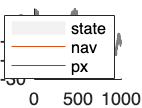


[LL,Res] = base_kf_missing(EstimParams,y); 
[a_sm, v_sm] = kf_smooth(Res.v_t, Res.invF_t, Res.L_t, Res.alfa_t(:,1:(end-1)), Res.P_t(:,:,1:(end-1)), Res.Z);

% the relationship between the two states
color = [0.5, 0.5, 0.5];
alpha=0.1;
figure;
hold on
plot(1:T, y(:,1:T));
confplot(1:T,a_sm(1,1:T),squeeze(sqrt(v_sm(1,1,1:T)) * 1.96)', color, alpha);
legend('px', 'nav','state');
hold off

% use the current version on real data before moving on and get the
% residuals and do diagonistic checks



% time-varying state space



% change the distribution and see it should perform worse


% t-distributed time-varying state space


% exact initialization